clearvars;
Nvec = 2:2:100;
for it =1:length(Nvec)
    N =Nvec(it);
    h = 2*pi/N;
    x = - pi + (1:N)' *h;
    u = exp(sin(x));
    uprime = cos(x).*u;

    e = ones(N,1);
    D = sparse(1:N,[2:N 1],2*e/3,N,N)...
        -sparse(1:N,[3:N 1 2],e/12, N, N);
    D4 =(D-D')/h;
    error4(it) = norm(D4*u - uprime,inf);
    
    column = [0 .5*(-1).^(1:N-1).*cot((1:N-1)*h/2)];
    DF = toeplitz(column, column([1 N:-1:2]));
    errorF(it) = norm(DF * u - uprime, inf);
end

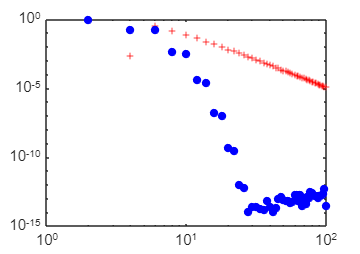

loglog(Nvec,error4,'r+',"MarkerSize",4), hold on
loglog(Nvec,errorF,'b.',"MarkerSize",15), hold on
hold off